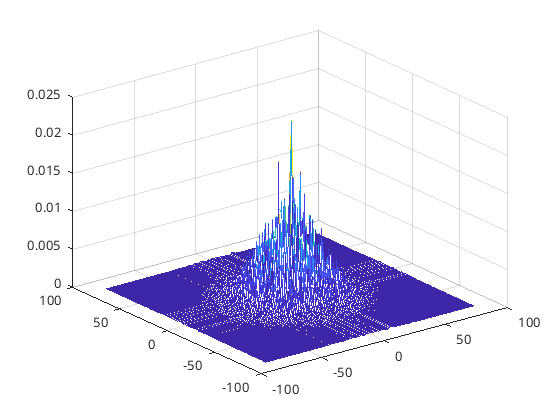

clear all
clc
imtool close all
close all
im1=imread('/home/tdelaselle/Documents/Codes/Codes persos Matlab/POC/Im1.png');
im2=imread('/home/tdelaselle/Documents/Codes/Codes persos Matlab/POC/Im2.png');
% im1 = imread('/home/tdelaselle/Bureau/1.png');
% im2 = imread('/home/tdelaselle/Bureau/1.png');
im1=rgb2gray(im1);
im2=rgb2gray(im2);
% i1=imcrop(im1,[296,264,17,17]);
% i2=imcrop(im2,[296,264,17,17]);
ima1=double(im1);
ima2=double(im2);

[Nx, Ny]=size(ima1);
Mx=(Nx-1)/2;
My=(Ny-1)/2;
nx=-Mx:1:Mx;
ny=-My:1:My;
w=hanning(Nx);% applying hanning window
w=w*w';
image1=ima1*w;
image2=ima2*w;
f1=fft2(ima1);
f2=fft2(ima2);
%image(f1);
n=f1.*conj(f2);
n1=n./abs(n);
n1(isnan(n1))=1;
h=fspecial('gaussian',[Nx,Ny],1.5);
n1=imfilter(n1,h);
result=ifft2(n1);
result=fftshift(abs(result));
figure;
mesh((-Mx:Mx),(-My:My),real(result));

% figure;
% % plot((-Mx:Mx),(result'));
% title('Plot of X- axis');
% figure;
% % plot((-Mx:Mx),(result));
% title('Plot of Y- axis');
rmax = max(max(result))

rmax = 0.0212

[x , y] = find(result == rmax);
x=ceil(Nx/2)-x 

x = -23

y=ceil(Nx/2)-y

y = -19